%laboratorio
%diseñar para mp=5% ts 5s

clear all
clc
s=tf('s');
G=zpk(20/((s+1)*(s+10)))

G =
 
       20
  ------------
  (s+10) (s+1)
 
Continuous-time zero/pole/gain model.



Tk=feedback(G,1)

Tk =
 
      20
  -----------
  (s+5) (s+6)
 
Continuous-time zero/pole/gain model.



pole(Tk)

ans =    -5.0000
   -6.0000


stepinfo(Tk)

ans = struct with fields:
         RiseTime: 0.6169
    TransientTime: 1.0738
     SettlingTime: 1.0738
      SettlingMin: 0.6013
      SettlingMax: 0.6666
        Overshoot: 0
       Undershoot: 0
             Peak: 0.6666
         PeakTime: 2.2013


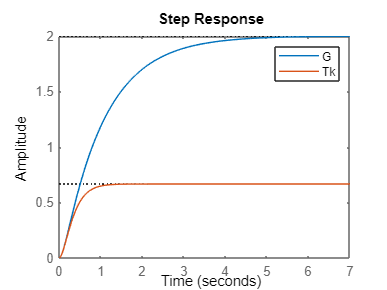

figure(2)
step(G,Tk),legend

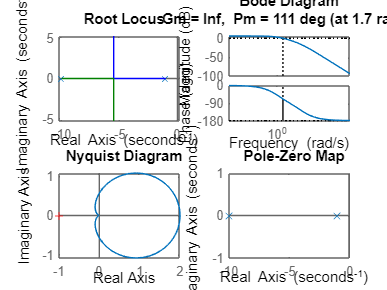

figure(3)
subplot(221),rlocus(G)
subplot(222),margin(G)
subplot(223),nyquist(G)
subplot(224),pzmap(G)

kp=dcgain(G)

kp = 2

kv=dcgain(G*s)

kv = 0

ka=dcgain(G*s^2)

ka = 0

eep=1/(1+kp)

eep = 0.3333

eev=1/kv

eev = Inf

eea=1/ka

eea = Inf

%ahopra aplicamos un integrador 
% s=tf('s');
% G1=zpk(20/((s+1)*(s+10)))
% Tk1=feedback(G1/s,1)
% pole(Tk1)
% stepinfo(Tk1)
% step(G1,Tk1),legend
% rlocus(Tk1)
% margin(Tk1)
% kp=dcgain(G1)
% kv=dcgain(G1*s)
% ka=dcgain(G1*s^2)
% eep=1/(1+kp)
% eev=1/kv
% eea=1/ka


%Segunda planta prueba 1
% s=tf('s');
% G2=(200/(s^2+30*s+200))
% Tk2=feedback(G2,1)
% pole(Tk2)
% stepinfo(Tk2)
% step(G2,Tk2),legend
% rlocus(Tk2)
% margin(Tk2)
% kp=dcgain(G2)
% kv=dcgain(G2*s)
% ka=dcgain(G2*s^2)


%Segunda planta prueba 2
% s=tf('s');
% G3=(200/(s^2+30*s+200))
% Tk3=feedback(G3/s,1)
% pole(Tk3)
% stepinfo(Tk3)
% step(G3,Tk3),legend
% rlocus(Tk3)
% margin(Tk3)
% kp=dcgain(G3)
% kv=dcgain(G3*s)
% ka=dcgain(G3*s^2)
% eep=1/(1+kp)
% eev=1/kv
% eea=1/ka